# **GEO4-1424A  - Applied Geophysics 2021**

# **Seismic Processing Lab**

# ***Exercise 2 - Sorting Seismic Data ***

## Contact: Ivan Vasconcelos (I.Vasconcelos@uu.nl), Leon Diekmann (L.D.Diekmann@uu.nl)

 In this exercise you will see how to shuffle around seismic data, without actually changing the data themselves. This data sorting takes place based on information that is usually given in the SEGY header (Remember this .segy extension ?? We said something about it in **Exercise 1**). In this header, for example, the positions of the sources and geophones are stored. In Matlab, we store the data and headers in seperate matrices. The sorting of these matrices needs to remain consistent throughout the processing.  

 In this exercise and the following ones, you will find highlighted, key questions you are required to address.

**Loading and plotting headers**

First, make sure to be in the "Reflection Seismics" working directory  and that all seismic commands can be found by Matlab by (re)loading the  paths as defined during the **Setup**: 

- Change to the directory U:\MATLAB\Reflection_Seismics\ with the **cd** command. 

-  Type ** path(pathdef)**. 

 Here you need to load a field dataset and assign headers to a separate variable.     

-  Type ** help segyread ** to figure out how to store also the header values into a variable. 

 Note that there is a difference between the trace headers and the  geometry of the whole dataset. The later contains specifications that  are true for all traces in a dataset. Now load the dataset and  corresponding headers:      

- Load the dataset, including headers, from the data\ directory into the matlab workspace. 

- Check by plotting the data whether you were successful in loading. 

Now you have loaded headers belonging to the traces:     

-  Plot the header values with the command ** plothdr **. 

 Four headers are plotted: the inline receiver position *xr*, the inline source position *xs*, the source-receiver distance or offset *d=xr-xs* and the midpoint *m=(xr+xs)/2*. Instead of the offset, it is common to use the half offset: *h=(xr-xs)/2*, which is the distance from the midpoint to either the source or the receiver.

## Key Question: Shot-Sorted Data [ 1/2 ]

- One of the headers is not consistent with the other 3. Which one? Why?

% start coding...



 Now:     

-  Delete the data matrix and header from the Matlab workspace by a simple ** clear ** command. 

*                                                                                                                                    Example of a plothdr window*

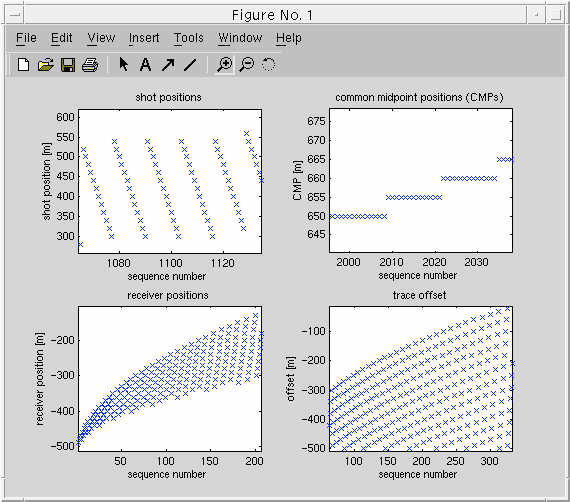

**Sorting headers alone**

 The previous example was rather straightforward. Usually, during  data-acquisition you do not have one shot; you have many. Consequently,  you have to load headers for all the data. You are now going to load  headers from a dataset where many shots were made during acquisition. 

-  Load the headers present in the data\ directory in your workspace using the ** load ** command, i.e., ** load H_SHT **. 

-  Run the command ** plothdr ** again. 

Now, some questions based on these plots of the geometry (for  answering these and the following questions, you might want to use the  zoom function in the plot window, or to reduce the number of traces  plotted by specifying a minimum and maximum trace-number in ** plothdr ** ): 

## Key Questions: Shot-Sorted Data [ 2/2 ]

-  How can you see that the data from acquisition is sorted per shot? 

-  Determine the number of shots. 

-  What is the receiver spacing in a common-shot gather *dxr* ? 

-  Why does the trace offset show repetitive upward-going lines? 

-  Why does the receiver position show the same repetitive upward-going lines but now with a general up going trend over it? 

**Sorting to Common Receiver Positions (CRP's)**

In the following, you are going to re-sort the shot-sorted headers  you loaded above, according to receiver-positions, CMP-positions and  offsets. For this, the function **sorthdr** is needed. First, study common-receiver gathers:

-  Use ** sorthdr ** for sorting the headers by receiver position. 

-  Plot the sorted headers by using **plothdr** again. 

-  Compare the plot with the one that you made for common-shot data. 

**Sorting to Common MidPoint Positions (CMP's)**

Next, you are going to analyse Common MidPoint gathers: 

-  Sort the header data to CMP's. 

## Key Questions: Midpoint-Sorted Data [3/3]

-  What would you expect to be the distance between subsequent CMPs? Explain your answer. 

-  Determine the actual distance between subsequent CMPs. 

-  Based on this, how many CMP-gathers are created? (You could use the functions ** max ** and ** min ** on the correct header-row to find the maximum and minimum value, respectively).

With CMP-gathers, the number of traces are varying at the beginning and end. You are going to analyse the number of traces within the CMP-gathers. The number of traces per CMP-gather can be analysed with the command ** analysefold **:  

-  Use the ** help ** command to find out how it works. 

-  Run the command ** analysefold ** to make a plot of the fold (i.e., the amount of traces) per CMP. 

-  Use this plot to verify the fold for the 4th CMP, the middle CMP and the three-but-last CMP. 

## Key Questions: Midpoint-Sorted Data [1/3]

-  In which gather the highest fold is reached (common-offset, common-shot, common-receiver or common-midpoint)? 

-  How high is this fold? 

 When continuing below:     

-  Delete the headers in the Matlab memory by a simple ** clear ** command. 

** Sorting data ***** and ***** headers **

 Above, you have sorted headers alone. Normally, there is always  seismic data associated with the headers; data and headers are sorted in one go. Data sorting can only take place based on information that is  given in the headers. You are going to sort the dataset * slope.segy * from the data\ directory.

- Load the data and headers with the ** segyread ** command. 

 From the number of rows of the data-matrix after loading you can  already notice the number of time samples per trace. The number of  columns represents the total amount of traces present in the dataset.  Determine the geometry by using ** plothdr **: 

## Key Questions: Slope Dataset [1/3]

-  Determine the number of shots, number of receivers, spacing between sources and spacing between receivers. 

 Later on, you need to compare a CMP with a shot:    

-  Select one shot in the middle and assign the shot-gather to a variable. 

 With the function ** sortdata **, both the data and the headers  are going to be sorted at the same time (takes a longer time since the  data need to be reshuffled). Start with sorting to Common Mid-Points:     

-  Use the **help** to find out what sort of output the function ** sortdata ** generates. 

-  Sort the data to CMP's. 

-  Plot a Common Mid-Point gather in the middle of the range (so plot a part of the data output of **sortdata**). 

-  Also plot the corresponding header data. 

## Key Questions: Slope Dataset [2/3]

-  What is the (offset) spacing between the traces in a CMP-gather ? 

-  Now also plot the middle shot-gather that you saved in memory earlier. 

 Compare this middle shot-gather with the middle CMP-gather: 

## Key Questions: Slope Dataset [3/3]

-  Comparing middle shot-gather with middle CMP-gather, what strikes you most ? Can you provide an explanation ? 

 In order to make the commands available for future exercises, the  commands you used for making CMP's should be stored in a script. This script  should start from reading the SEGY data and end with CMP-sorted data,  so:     

-  Make this script - into the ***Matlab Live Script*** format - unless you already used this Script to do it **:-)**. 

- Collect the Key Questions above, your answers and any additional thoughts as text sections accompanying the sections of your script. 

 When you yourself are convinced the script works: → [Show the instructor that your script works.]